# Parcial 2 Control y Sistemas

**Nombre y apellido alumno: **

## Objetivos

Proponer una solución a la siguiente problemática utilizando conceptos de la materia y el criterio de ingeniería construido en las clases. 

Guardar este template en su directorio de trabajo con el siguiente nombre (colocando su nombre). Lo mismo para el enunciado de simulink/simscape.

`parcial2_livescript_NOMBRE_APELLIDO.mlx   (live script)`

`parcial2_planta_NOMBRE_APELLIDO.slx   (simulink/simscape)`

Una vez finalizado el examen enviar los 5 archivos: 1 live script + 4 archivos de simulink que se realizarán a medida que avance en el examen a las siguiente dirección de correo:

`carloshernangarrido@gmail.com`

    `CC: `

    `mauricio.caceres@ingenieria.uncuyo.edu.ar`

## Sección 1: Diseño y validación de planta

Construya un modelo en simulink usando simscape (mecánica traslacional) de la suspensión de un cuarto de vehículo (un colectivo).Los parámetros se dan abajo.Las perturbaciones del terreno aparecen a los 50 segundos y se modelan como un ruido de `1 m/s^2 RMS` (el bloque Band-Limited White Noise ya está configurado). SI EL MODELO ES CORRECTO, generan compresiones de la suspensión de 3 a 4 cm pico.

Guarde la solución en un archivo con nombre:  "`parcial2_planta_NOMBRE_APELLIDO.slx"`

%% Parameters (golden car)
clc
clear
close all

m_s = 3000;  % Sprung mass (masa del chasis por rueda) (kg)
k_s = 63.3*m_s;  % Spring stiffness (rigidez del resorte) (N/m)
c_s = 6*m_s;  % Damping coefficient (coeficiente de amortiguamiento del amortiguador) (Ns/m)
k_t = 653*m_s;  % Tire stiffness (rigidez del neumático) (N/m)
c_t = 0;  % Tire damping (Ns/m)
m_u = 0.15*m_s;  % (masa de la rueda) Unsprung mass (kg)

## Sección 2: Diseño de control PID

- Haga una copia del modelo de simulink/simscape. Coloque como nombre

`parcial2_PID_NOMBRE_APELLIDO.slx `

Considerando un sensor ideal de distancia para medir la compresión de la suspensión: Implemente un PID para que el colectivo descienda y permita el ingreso de pasajeros. 

Este controlador, cuando el chofer da un escalón a la referencia de -15 cm a los 10 s, debe hacer que la suspensión se comprima 15 cm,  sin error en estado estacionario, sin sobre-impulso y con un tiempo de establecimiento de menos de 1.0 s.

Por otra parte, cuando sube el pasajero, modelado como perturbación tipo escalón de 700 N a los 20 s, el controlador debe rechazar la perturbación con un tiempo de establecimiento de menos de 1.0 s.

Para esto puede usar el comando 

%pidTuner(H, 'PID');

y obtener las ganancias por tanteo observando la tabla mostrada al pulsar el botón` Show Parameters.`Completar  los valores faltantes en las matrices a continuación para poder ejecutar el script

%% Diseño del PID
% x = [pos_u
%      pos_s
%      vel_u
%      vel_s]

M = [m_u 0
     0   m_s];
K = [k_s+k_t -k_s
     -k_s     k_s]

K =      2148900     -189900
     -189900      189900


C = [c_s+c_t -c_s
     -c_s     c_s]

C =        18000      -18000
      -18000       18000


A_ss = [ 0 0 1 0 
         0 0 0 1
        -M\K -M\C] 

A_ss = 	1.0e+03 *

         0         0    0.0010         0
         0         0         0    0.0010
   -4.7753    0.4220   -0.0400    0.0400
    0.0633   -0.0633    0.0060   -0.0060



B_ss = [ 0
         0
         (M^-1) * [ -1
                    1 ]]

B_ss =          0
         0
   -0.0022
    0.0003



C_ss = [ 1 -1 0 0]

C_ss =      1    -1     0     0


D_ss = [ 0 ]

D_ss = 0

     
H = tf(ss(A_ss, B_ss, C_ss, D_ss))

H =
 
        -0.002556 s^2 + 4.54e-18 s - 1.451
  -----------------------------------------------
  s^4 + 46 s^3 + 4839 s^2 + 2.612e04 s + 2.756e05
 
Continuous-time transfer function.



stepinfo(H)

ans = struct with fields:
        RiseTime: 0.2246
    SettlingTime: 1.4353
     SettlingMin: -6.8378e-06
     SettlingMax: -4.7432e-06
       Overshoot: 29.8492
      Undershoot: 0
            Peak: 6.8378e-06
        PeakTime: 0.4468


%pidTuner(H, 'PID');
%VALORES OBTENIDOS CON PID TUNER + UN AJUSTE FINO
kp = -3.594332440437744e+05

kp = -3.5943e+05

ki = -1.369657386898867e+06

ki = -1.3697e+06

kd = -4.234977837301392e+04

kd = -4.2350e+04

C= tf([kd,kp,ki],[1,0])

C =
 
  -4.235e04 s^2 - 3.594e05 s - 1.37e06
  ------------------------------------
                   s
 
Continuous-time transfer function.




sys_controlado = feedback(H*C,1)

sys_controlado =
 
    108.2 s^4 + 918.6 s^3 + 6.495e04 s^2 + 5.216e05 s + 1.988e06
  -----------------------------------------------------------------
  s^5 + 154.2 s^4 + 5757 s^3 + 9.107e04 s^2 + 7.971e05 s + 1.988e06
 
Continuous-time transfer function.



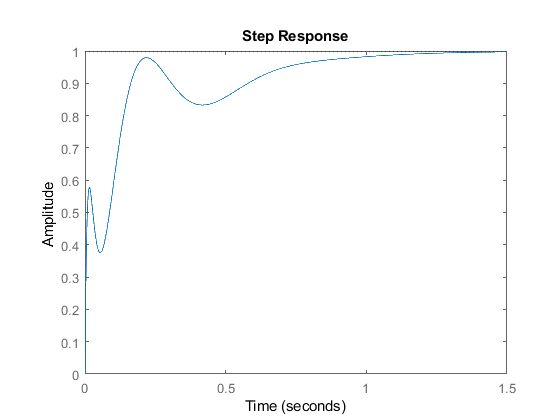

step(sys_controlado)

stepinfo(sys_controlado)

ans = struct with fields:
        RiseTime: 0.1615
    SettlingTime: 0.9619
     SettlingMin: 0.8328
     SettlingMax: 0.9987
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9987
        PeakTime: 1.6935


Bd = [0;1/m_s;0;0] % matriz de perturbaciones. Se puede deducir pensando que la fuerza se aplica en el chasis.

Bd = 	1.0e+-3 *

         0
    0.3333
         0
         0


Hd = tf(ss(A_ss, Bd, C_ss, D_ss)) % Funcion de transf. con respecto a perturbaciones. Lo hice para ver su stepinfo

Hd =
 
  -0.0003333 s^3 - 0.01533 s^2 - 1.451 s - 8.707
  -----------------------------------------------
  s^4 + 46 s^3 + 4839 s^2 + 2.612e04 s + 2.756e05
 
Continuous-time transfer function.



sys_perturbado = feedback(1,C*H)*Hd

sys_perturbado =
 
                                                                                                            
  -0.0003333 s^8 - 0.03067 s^7 - 3.769 s^6 - 158.4 s^5 - 7914 s^4 - 8.426e04 s^3 - 6.273e05 s^2 - 2.399e06 s
                                                                                                            
  ----------------------------------------------------------------------------------------------------------
                                                                                                            
  s^9 + 200.2 s^8 + 1.769e04 s^7 + 1.128e06 s^6 + 3.715e07 s^5 + 6.722e08 s^4 + 7.914e09 s^3 + 5.554e10 s^2 
                                                                                                            
                                                                                     + 2.716e11 s + 5.477e11
                                                                                                            


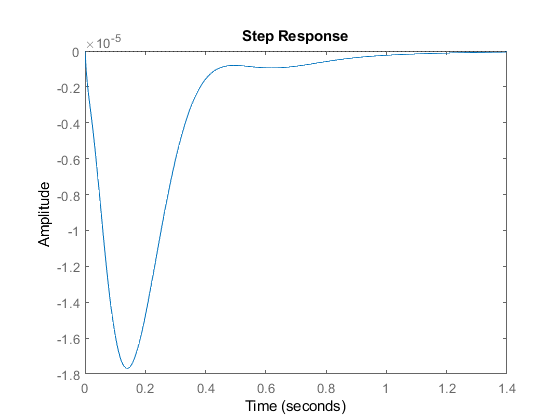

step(sys_perturbado)

stepinfo(sys_perturbado)

ans = struct with fields:
        RiseTime: 0
    SettlingTime: 0.9085
     SettlingMin: -1.7682e-05
     SettlingMax: -3.2433e-08
       Overshoot: Inf
      Undershoot: Inf
            Peak: 1.7682e-05
        PeakTime: 0.1398


## Sección 3: Limitación de la acción de control del sistema

- Haga una copia del modelo de simulink/simscape. Coloque como nombre

`parcial2_PID_avanzado_NOMBRE_APELLIDO.slx`

Modifique el controlador de manera que la acción de control nunca supere los 40000 N en valor absoluto. Tendrá que agregar algún/algunos bloque/bloques. Se permite degradación del desempeño ante el escalón en la referencia, pero ante el escalón de la perturbación debe mantener la dinámica

Controlador I-PD

Gi = tf(ki,[1 0])

Gi =
 
  -1.37e06
  --------
     s
 
Continuous-time transfer function.



Gpd = tf([kd kp],1)

Gpd =
 
  -4.235e04 s - 3.594e05
 
Continuous-time transfer function.



sys_con_I_PD = feedback(H,(Gi+Gpd))*Gi

sys_con_I_PD =
 
                  3500 s^3 - 6.218e-12 s^2 + 1.988e06 s
  ---------------------------------------------------------------------
  s^6 + 154.2 s^5 + 5757 s^4 + 9.107e04 s^3 + 7.971e05 s^2 + 1.988e06 s
 
Continuous-time transfer function.



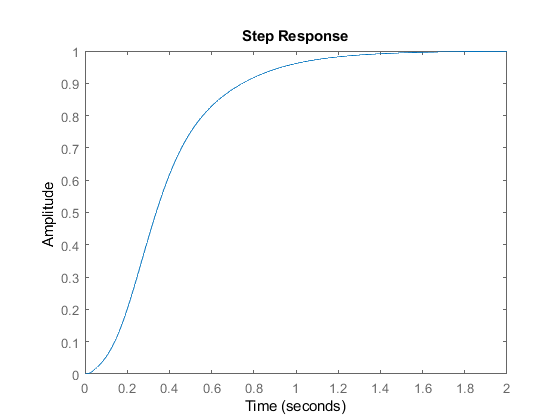

step(sys_con_I_PD)

stepinfo(sys_con_I_PD)

ans = struct with fields:
        RiseTime: 0.6067
    SettlingTime: 1.1744
     SettlingMin: 0.9007
     SettlingMax: 0.9994
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9994
        PeakTime: 2.1107


stepinfo(sys_con_I_PD)

ans = struct with fields:
        RiseTime: 0.6067
    SettlingTime: 1.1744
     SettlingMin: 0.9007
     SettlingMax: 0.9994
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9994
        PeakTime: 2.1107


sys_per_I_PD = feedback(1, H*(Gi+Gpd))*Hd

sys_per_I_PD =
 
                                                                                                            
  -0.0003333 s^8 - 0.03067 s^7 - 3.769 s^6 - 158.4 s^5 - 7914 s^4 - 8.426e04 s^3 - 6.273e05 s^2 - 2.399e06 s
                                                                                                            
  ----------------------------------------------------------------------------------------------------------
                                                                                                            
  s^9 + 200.2 s^8 + 1.769e04 s^7 + 1.128e06 s^6 + 3.715e07 s^5 + 6.722e08 s^4 + 7.914e09 s^3 + 5.554e10 s^2 
                                                                                                            
                                                                                     + 2.716e11 s + 5.477e11
                                                                                                            
 


step(sys_per_I_PD)

stepinfo(sys_per_I_PD) %%Vemos que las perturbaciones no cambian.

ans = struct with fields:
        RiseTime: 0
    SettlingTime: 0.9085
     SettlingMin: -1.7682e-05
     SettlingMax: -3.2433e-08
       Overshoot: Inf
      Undershoot: Inf
            Peak: 1.7682e-05
        PeakTime: 0.1398


## Sección 4: Control LQR

- Haga una copia del modelo de simulink/simscape de la sección 1

- Elimine el bloque PID, pero mantenga el modelo de la planta en simscape. Coloque el nombre

`parcial2_LQR_NOMBRE_APELLIDO.slx `

Agregue un controlador LQR ($K$), con seguimiento de referencia por feedforward ($k_r$), y acción integral ($k_i$). LAs matrices de ganancias $K$, $k_i$ y $k_r$ deben estar explícitas en el diagrama en bloques. 

No es necesario diseñar los valores óptimos para $K$, $k_i$ y $k_r$ (puede asignar valores 1 a todos los elementos como prueba), pero el modelo debe poder ejecutarse. Es decir, las dimensiones de las matrices deben ser consistentes para que simulink no de error.

%Sé que no es necesario hacer esto, pero lo quise hacer igual. Es mi forma
%de saber si el modelo en simulink está bien conectado.
Aaug = [A_ss [0;0;0;0]; C_ss 0]

Aaug = 	1.0e+03 *

         0         0    0.0010         0         0
         0         0         0    0.0010         0
   -4.7753    0.4220   -0.0400    0.0400         0
    0.0633   -0.0633    0.0060   -0.0060         0
    0.0010   -0.0010         0         0         0


Baug = [B_ss;0]

Baug =          0
         0
   -0.0022
    0.0003
         0


a1 = 10;
a2 = 10;
dx_max = 0.1;
e_int_max = 10;
umax = 40000;
ro = 10;
Qy = [a1/dx_max^2 0; 0 a2/e_int_max^2]

Qy = 	1.0e+03 *

    1.0000         0
         0    0.0001


Qx = [C_ss 0; 0 0 0 0 1]'*Qy*[C_ss 0; 0 0 0 0 1]

Qx = 	1.0e+03 *

    1.0000   -1.0000         0         0         0
   -1.0000    1.0000         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0    0.0001


Qu = ro/umax^2

Qu = 6.2500e-09

K_lqr = lqr(Aaug,Baug,Qx,Qu)

K_lqr = 	1.0e+05 *

   -1.6247    2.5326   -0.0045    0.2348   -0.0400


K = K_lqr(1,1:end-1)

K = 	1.0e+05 *

   -1.6247    2.5326   -0.0045    0.2348


ki_lqr = K_lqr(end)

ki_lqr = -4.0000e+03

M_lqr = A_ss - B_ss*K;
X_lqr = C_ss * (M_lqr \ B_ss) % M \B es equivalente a inv(M)*Bu pero más estable

X_lqr = 2.2565e-06


kr = -1 / X_lqr

kr = -4.4316e+05